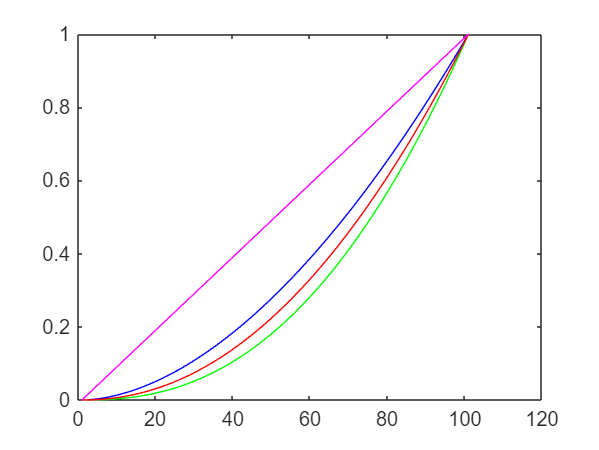

load TRC_display.mat

% upg 1.1
plot(TRCb, 'b')
hold on

plot(TRCg, 'g')
hold on

plot(TRCr, 'r')
hold on

linear = 0:0.01:1;
plot(linear, 'm')


% more blue, less green


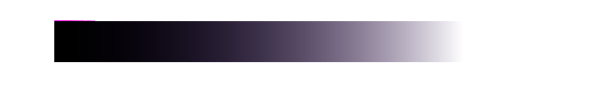

% upg 1.2

load Ramp_display.mat
load Ramp_linear.mat

imshow(Ramp_display)

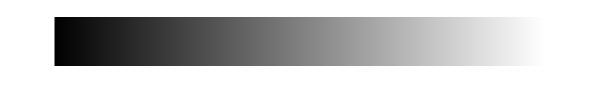


imshow (Ramp_linear)

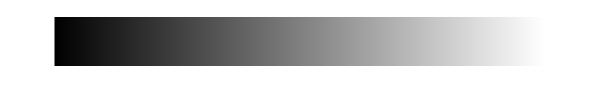


% Calibration

x = 0:0.01:1;

ramp_dispR = interp1(TRCr, x, Ramp_display(:,:,1));
ramp_dispG = interp1(TRCg, x, Ramp_display(:,:,2));
ramp_dispB = interp1(TRCb, x, Ramp_display(:,:,3));


RampDispCorrection = cat(3, ramp_dispR, ramp_dispB, ramp_dispG);
imshow(RampDispCorrection)

% upg 1.3

Yr = 2.1;
Yg = 2.4;
Yb = 1.8;

Dmax = 1;

D_R = Dmax*(Ramp_display(:,:,1)/ Dmax).^(1/Yr);
D_G = Dmax*(Ramp_display(:,:,2)/ Dmax).^(1/Yg);
D_B = Dmax*(Ramp_display(:,:,3)/ Dmax).^(1/Yb);

gammaRampCorrection = cat(3, D_R, D_G, D_B);
imshow(gammaRampCorrection)

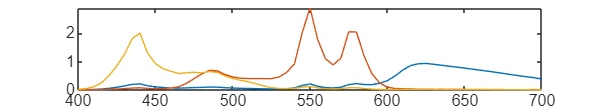

% upg 2.1

load DLP.mat

wavelength = 400:5:700;

plot(wavelength, DLP)


% grön starkast, blå mellan och röd svagast


% upg 2.2

load RGB_raw.mat
load xyz.mat
load illum.mat
load XYZ_ref.mat


k = 100./(CIED65*xyz(:,2));

% convert spectral radiance to XYZ
s_rgb = DLP*RGB_raw;
observer = xyz' * s_rgb * k;
[L, a, b] = xyz2lab(observer(1,:)', observer(2,:)', observer(3,:)');

REF_Lab = zeros(3,20);
REF_Lab(1,:) = L;
REF_Lab(2,:) = a;
REF_Lab(3,:) = b;


% From xyz to lab
[L, a, b] = xyz2lab(XYZ_ref(1,:)', XYZ_ref(2,:)', XYZ_ref(3,:)');

XYZ_REF_Lab = zeros(3,20);
XYZ_REF_Lab(1,:) = L;
XYZ_REF_Lab(2,:) = a;
XYZ_REF_Lab(3,:) = b;


calcDist = sqrt((XYZ_REF_Lab(1,:)-REF_Lab(1,:)).^2+(XYZ_REF_Lab(2,:)-REF_Lab(2,:)).^2+(XYZ_REF_Lab(3,:)-REF_Lab(3,:)).^2);

% calcDist2 = CalcED(XYZ_REF_Lab', REF_Lab)

maxVal = max(calcDist)

maxVal = 51.6380

meanVal= mean(calcDist)

meanVal = 22.3508

% upg 2.3

load RGB_cal.mat

k = 100./(CIED65*xyz(:,2));

% convert spectral radiance to XYZ
s_rgb = DLP*RGB_cal;
observer = xyz' * s_rgb * k;
[L, a, b] = xyz2lab(observer(1,:)', observer(2,:)', observer(3,:)');

REF_Lab = zeros(3,20);
REF_Lab(1,:) = L;
REF_Lab(2,:) = a;
REF_Lab(3,:) = b;


% From xyz to lab
[L, a, b] = xyz2lab(XYZ_ref(1,:)', XYZ_ref(2,:)', XYZ_ref(3,:)');

XYZ_REF_Lab = zeros(3,20);
XYZ_REF_Lab(1,:) = L;
XYZ_REF_Lab(2,:) = a;
XYZ_REF_Lab(3,:) = b;


calcDist2 = sqrt((XYZ_REF_Lab(1,:)-REF_Lab(1,:)).^2+(XYZ_REF_Lab(2,:)-REF_Lab(2,:)).^2+(XYZ_REF_Lab(3,:)-REF_Lab(3,:)).^2);


maxVal2 = max(calcDist2)

maxVal2 = 33.5351

meanVal2 = mean(calcDist2)

meanVal2 = 16.9236

% upg 3.1

k = 100./(CIED65*xyz(:,2));

Acrt = xyz' * DLP * k; % like the formula
display(Acrt)

Acrt =    38.0922   55.7160   19.9274
   22.6080   87.9484   11.4011
   10.9203   16.5373   92.4433


% upg 3.2

load XYZ_est.mat


k = 100./(CIED65*xyz(:,2));


depInput = inv(Acrt) * XYZ_est

depInput =     0.7491    0.3818    0.0742    0.1615    0.0060    0.2044    0.7004    0.1009    0.5019    0.0495    0.2964    0.3718    0.2326    0.1363    0.1461    0.2187   -0.0912    0.4061    0.6730    0.3704
    0.5099    0.1543    0.0773    0.1217    0.4973    0.3095    0.4826    0.0399    0.3035    0.0311    0.0337    0.1004    0.0645    0.2549    0.2897    0.0426    0.3511    0.1029    0.5939    0.2922
    0.4799    0.2366    0.1327    0.1859    0.4524    0.3594   -0.0630    0.0501   -0.0584    0.0355    0.1350    0.0566    0.0862    0.0218    0.6421    0.1578    0.5430    0.0088    0.0092    0.3111




SpectralXYZ = k .* ((DLP * depInput)' *xyz)';
display(SpectralXYZ);

SpectralXYZ =    66.5096   27.8573    9.7750   16.6392   36.9511   32.1922   52.3149    7.0672   34.8667    4.3226   15.8613   20.8865   14.1754   19.8283   34.5017   13.8445   26.9130   21.3759   58.9062   36.5895
   67.2542   24.9010    9.9852   16.4765   49.0317   35.9394   57.5626    6.3649   37.3760    4.2559   11.2072   17.8821   11.9189   25.7486   36.1026   10.4850   35.0129   18.3282   67.5508   37.6216
   60.9787   28.5960   14.3552   20.9662   50.1102   40.5785    9.8074    6.3964    5.0991    4.3336   16.2770   10.9571   11.5759    7.7201   65.7413   17.6776   55.0127    6.9452   18.0166   37.6376



% calcDist3 = sqrt((SpectralXYZ(1,:)-XYZ_ref(1,:)).^2+(SpectralXYZ(2,:)-XYZ_ref(2,:)).^2+(SpectralXYZ(3,:)-XYZ_ref(3,:)).^2);

calcDist4 = CalcED(XYZ_ref', SpectralXYZ')

calcDist4 =     0.0337
    2.3631
    1.6165
    1.1127
    0.3276
    1.0344
    0.9939
    0.2794
    0.8178
    1.5029



% maxVal3 = max(calcDist3)
% meanVal3 = mean(calcDist3)

maxVal4 = max(calcDist4)

maxVal4 = 3.1053

meanVal4 = mean(calcDist4)

meanVal4 = 1.0238

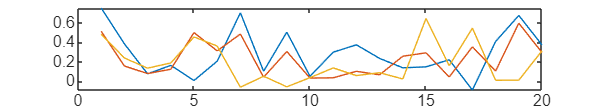

% upg 3.3

plot(depInput')

% negative values can be found, this can happen when you transform between
% different color spaces and a value in one color gets wrongly represented
% in the other



% upg 3.4

depMin = min(min(depInput));
depMax = max(max(depInput));

scaledDep = (depInput(:,:,:) - depMin) / (depMax - depMin);
minScaled = min(min(scaledDep))

minScaled = 0

maxScaled = max(max(scaledDep))

maxScaled = 1

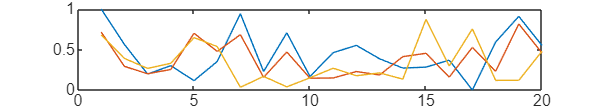


plot(scaledDep')


% re-doing the process in 3.2 with scaled dep

k = 100./(CIED65*xyz(:,2));


SpectralXYZ = k .* ((DLP * scaledDep)' *xyz)';
display(SpectralXYZ);

SpectralXYZ =    91.4919   45.4932   23.9742   32.1430   56.3154   50.6520   74.5993   20.7517   53.8348   17.4854   31.2172   37.1975   29.2109   35.9382   53.4005   28.8171   44.3694   37.7800   82.4434   55.8851
   93.2701   42.8672   25.1164   32.8415   71.5842   56.0035   81.7366   20.8081   57.7132   18.2982   26.5707   34.5143   27.4177   43.8759   56.1978   25.7113   54.9010   35.0451   93.6231   58.0055
   85.5787   47.0413   30.0938   37.9614   72.6446   61.3013   24.6817   20.6224   19.0786   18.1676   32.3809   26.0499   26.7863   22.1977   91.2466   34.0477   78.4788   21.2755   34.4511   57.8014



calcDist5 = CalcED(XYZ_ref', SpectralXYZ');

maxVal5 = max(calcDist5)

maxVal5 = 24.8719

meanVal5 = mean(calcDist5)

meanVal5 = 17.4072


% we get bigger values beacuase we have adjusted all the values to be
% between 0 and 1 and so we´re not necessarily getting the correct color but it works for the projector 


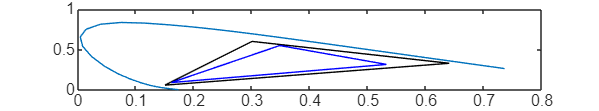

% upg 3.5 
clf 
plot_chrom_sRGB(Acrt)
hold off

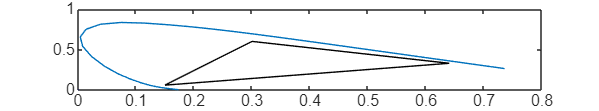

plot_chrom_sRGB((DLP * depInput))

% upg 3.6

% taken from lab1
S_rgb_N = DLP*depInput;
normalized_spectrum = xyz'*S_rgb_N;
normalized_output = normalized_spectrum'*k;

XYZ_D65_Ref = xyz'*(CIED65 .* chips20)'*Norm_factor;


ref_1 = XYZ_D65_Ref(:,1);

rep_1 = normalized_output(1,:);

[L, a, b] =  xyz2lab(rep_1(:,1)', rep_1(:,2)', rep_1(:,3)');
REF_LAB_N = zeros(3,1);
REF_LAB_N(1,:) = L;
REF_LAB_N(2,:) = a;
REF_LAB_N(3,:) = b;

[L, a, b] =  xyz2lab(ref_1(1,:)', ref_1(2,:)', ref_1(3,:)');
XYZ_ref_lab = zeros(3,1);
XYZ_ref_lab(1,:) = L;
XYZ_ref_lab(2,:) = a;
XYZ_ref_lab(3,:) = b;


calcDist6 = CalcED(XYZ_ref_lab', REF_LAB_N')

calcDist6 = 0.9047


maxVal6 = max(calcDist6)

maxVal6 = 0.9047

meanVal6 = mean(calcDist6)

meanVal6 = 0.9047

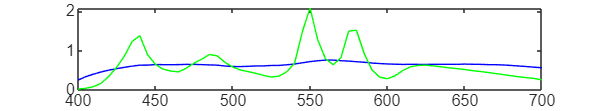


chipxyz = chips20(1,:).*CIED65;
plot(400:5:700, chipxyz, 'blue');
hold on
plot(400:5:700,s_rgb(:,1), 'green')
hold off



%% better result if would have used the clamp method, instead we move the spectrum fo it to fit